%% DISEÑO INICIAL MPC PARA IPC
% Modelo: beta_tilt/beta_yaw -> Mtilt/Myaw
% Objetivo: reducir cargas con restricciones de pitch y rate.

clear; close all; clc;

%% Rutas

rootDir = fullfile(getenv('USERPROFILE'), 'Desktop', 'TFM_OpenFast');
linDir  = fullfile(rootDir, 'Resultados', 'ModeloLineal_v16');
outDir  = fullfile(rootDir, 'Resultados', 'MPC_IPC');

if ~exist(outDir, 'dir')
    mkdir(outDir);
end

%% Comprobar toolbox MPC

fprintf('\nComprobando MPC Toolbox...\n');


Comprobando MPC Toolbox...



hasMPC = exist('mpc','file') == 2;

if hasMPC
    disp("MPC Toolbox disponible.");
else
    warning("No se encuentra la función mpc. Puede faltar Model Predictive Control Toolbox.");
end

MPC Toolbox disponible.



%% Cargar modelo IPC MBC

load(fullfile(linDir, 'modelo_ipc_mbc_desacoplado_v16.mat'), ...
    'sys_ipc_mbc', 'Kdec');

disp("Modelo IPC MBC cargado:");

Modelo IPC MBC cargado:


disp(sys_ipc_mbc);

  2×2 ss array with properties:

                A: [922×922 double]
                B: [922×2 double]
                C: [2×922 double]
                D: [2×2 double]
                E: []
          Offsets: []
           Scaled: 0
        StateName: {922×1 cell}
        StatePath: {922×1 cell}
        StateUnit: {922×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [2×1 double]
      OutputDelay: [2×1 double]
        InputName: {2×1 cell}
        InputUnit: {2×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {2×1 cell}
       OutputUnit: {2×1 cell}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]




% sys_ipc_mbc:
% entradas: beta_tilt, beta_yaw [rad]
% salidas:  Mtilt, Myaw [kN*m]

%% Separar parte estable y reducir modelo

Gfull = sys_ipc_mbc;

try
    [Gstable, Gunstable] = stabsep(Gfull);

    fprintf('\nSeparación estable/inestable realizada.\n');
    fprintf('Orden modelo completo: %d\n', order(Gfull));
    fprintf('Orden modelo estable:  %d\n', order(Gstable));
    fprintf('Orden inestable:       %d\n', order(Gunstable));

catch ME
    warning("No se pudo aplicar stabsep. Se usará el modelo completo.");
    disp(ME.message);
    Gstable = Gfull;
end


Separación estable/inestable realizada.


Orden modelo completo: 922


Orden modelo estable:  921


Orden inestable:       1



orden_red = 12;

try
    Gred = balred(Gstable, orden_red);
catch
    warning("balred ha fallado con orden 12. Se prueba orden 20.");
    orden_red = 20;
    Gred = balred(Gstable, orden_red);
end

Gred = minreal(Gred);

fprintf('\nModelo reducido para MPC creado.\n');


Modelo reducido para MPC creado.


fprintf('Orden reducido: %d\n', order(Gred));

Orden reducido: 12



%% Escalado de unidades para MPC

% Entrada original: rad
% Queremos que el MPC trabaje en grados:
% beta_rad = beta_deg * pi/180

% Salida original: kN*m
% Queremos salidas en MN*m:
% M_MNm = M_kNm / 1000

Gmpc_c = (1/1000) * Gred * (pi/180);

Gmpc_c.InputName = {'beta_tilt_deg','beta_yaw_deg'};
Gmpc_c.OutputName = {'Mtilt_MNm','Myaw_MNm'};

disp("Modelo continuo escalado para MPC:");

Modelo continuo escalado para MPC:


disp(Gmpc_c);

  2×2 ss array with properties:

                A: [12×12 double]
                B: [12×2 double]
                C: [2×12 double]
                D: [2×2 double]
                E: []
          Offsets: []
           Scaled: 0
        StateName: {12×1 cell}
        StatePath: {12×1 cell}
        StateUnit: {12×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [2×1 double]
      OutputDelay: [2×1 double]
        InputName: {2×1 cell}
        InputUnit: {2×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {2×1 cell}
       OutputUnit: {2×1 cell}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]




%% Eliminar término directo D para compatibilidad con MPC

Gmpc_c = ss(Gmpc_c);

[Ampc,Bmpc,Cmpc,Dmpc] = ssdata(Gmpc_c);

disp("Matriz D original del modelo MPC:");

Matriz D original del modelo MPC:


disp(Dmpc);

   -1.2204    0.3181
   -0.4808   -0.6490




% El MPC de MATLAB no permite feedthrough directo MV -> salida.
% Se elimina el término directo, manteniendo la dinámica A,B,C.
Dmpc_zero = zeros(size(Dmpc));

Gmpc_c_nod = ss(Ampc, Bmpc, Cmpc, Dmpc_zero);
Gmpc_c_nod.InputName = Gmpc_c.InputName;
Gmpc_c_nod.OutputName = Gmpc_c.OutputName;

disp("Modelo continuo sin feedthrough directo:");

Modelo continuo sin feedthrough directo:


disp(Gmpc_c_nod);

  2×2 ss array with properties:

                A: [12×12 double]
                B: [12×2 double]
                C: [2×12 double]
                D: [2×2 double]
                E: []
          Offsets: []
           Scaled: 0
        StateName: {12×1 cell}
        StatePath: {12×1 cell}
        StateUnit: {12×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [2×1 double]
      OutputDelay: [2×1 double]
        InputName: {2×1 cell}
        InputUnit: {2×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {2×1 cell}
       OutputUnit: {2×1 cell}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]




%% Discretización

Ts = 0.1;   % tiempo de muestreo MPC [s]

Gmpc_d = c2d(Gmpc_c_nod, Ts, 'zoh');

disp("Modelo discreto para MPC:");

Modelo discreto para MPC:


disp(Gmpc_d);

  2×2 ss array with properties:

                A: [12×12 double]
                B: [12×2 double]
                C: [2×12 double]
                D: [2×2 double]
                E: []
          Offsets: []
           Scaled: 0
        StateName: {12×1 cell}
        StatePath: {12×1 cell}
        StateUnit: {12×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [2×1 double]
      OutputDelay: [2×1 double]
        InputName: {2×1 cell}
        InputUnit: {2×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {2×1 cell}
       OutputUnit: {2×1 cell}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0.1000
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]




fprintf('\nEstabilidad modelo reducido discreto:\n');


Estabilidad modelo reducido discreto:


disp(isstable(Gmpc_d));

   1



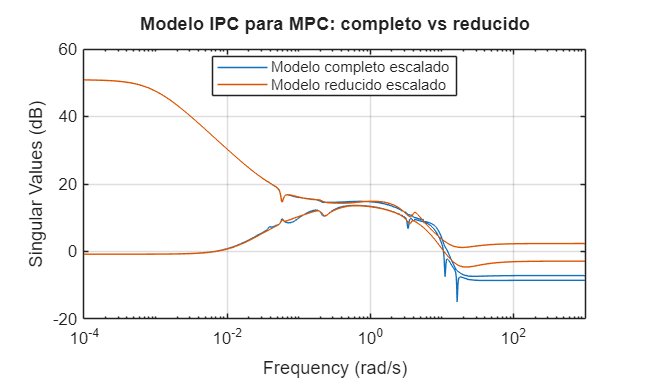


%% Comparación frecuencia modelo completo vs reducido

figure;
sigma((1/1000)*Gfull*(pi/180), Gmpc_c);
grid on;
legend('Modelo completo escalado','Modelo reducido escalado','Location','best');
title('Modelo IPC para MPC: completo vs reducido');

saveas(gcf, fullfile(outDir, 'modelo_mpc_completo_vs_reducido.png'));


%% Crear objeto MPC básico

if hasMPC

    Hp = 80;     % horizonte de predicción: 80*0.1 = 8 s
    Hc = 10;     % horizonte de control: 1 s

    mpcobj = mpc(Gmpc_d, Ts, Hp, Hc);

    % Restricciones sobre beta_tilt/beta_yaw en grados
    betaMax_deg = 0.5;
    betaRateMax_deg_s = 2.0;
    betaRateMax_step = betaRateMax_deg_s * Ts;

    for i = 1:2
        mpcobj.MV(i).Min = -betaMax_deg;
        mpcobj.MV(i).Max =  betaMax_deg;

        mpcobj.MV(i).RateMin = -betaRateMax_step;
        mpcobj.MV(i).RateMax =  betaRateMax_step;
    end

    % Pesos iniciales
    mpcobj.Weights.OutputVariables = [1 1];
    mpcobj.Weights.ManipulatedVariables = [0.2 0.2];
    mpcobj.Weights.ManipulatedVariablesRate = [0.6 0.6];

    disp("Pesos finales del MPC:");
    disp(mpcobj.Weights);
    disp("Objeto MPC creado:");
    disp(mpcobj);

    save(fullfile(outDir, 'mpc_ipc_inicial.mat'), ...
    'mpcobj', 'Gmpc_c', 'Gmpc_c_nod', 'Gmpc_d', ...
    'Gred', 'Gstable', ...
    'Ts', 'Hp', 'Hc', 'betaMax_deg', 'betaRateMax_deg_s');

else
    save(fullfile(outDir, 'modelo_mpc_ipc_sin_toolbox.mat'), ...
        'Gmpc_c', 'Gmpc_d', 'Gred', 'Gstable', 'Ts');

    warning("Modelo preparado, pero no se pudo crear mpcobj porque falta MPC Toolbox.");
end

-->"Weights.ManipulatedVariables" is empty. Assuming default 0.00000.
-->"Weights.ManipulatedVariablesRate" is empty. Assuming default 0.10000.
-->"Weights.OutputVariables" is empty. Assuming default 1.00000.


Pesos finales del MPC:


        ManipulatedVariables: [0.2000 0.2000]
    ManipulatedVariablesRate: [0.6000 0.6000]
             OutputVariables: [1 1]
                         ECR: 100000



Objeto MPC creado:


  2×2 mpc array with properties:

                      Ts: 0.1000
       PredictionHorizon: 80
          ControlHorizon: 10
                   Model: [1×1 struct]
    ManipulatedVariables: [1×2 struct]
         OutputVariables: [1×2 struct]
    DisturbanceVariables: []
                 Weights: [1×1 struct]
               Optimizer: [1×1 struct]
                   Notes: {}
                UserData: []
                 History: [2026 8 17 19 21 53.8140]




disp("Bloque inicial MPC terminado.");

Bloque inicial MPC terminado.


disp(outDir);

C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\MPC_IPC


PRUEBA OFFLINE


Leyendo caso para MPC offline: Base - 16 m/s constante


Reading from the file C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\CasoA_v16_constante\IEA-15-240-RWT-UMaineSemi.outb with heading: 
   "Predictions were generated on 11-Aug-2026 at 18:11:56 using OpenFAST, compiled on Aug 06 2025 at 19:22:48 as a 64-bit application using single precision at commit v4.1.2 linked with  NWTC Subroutine Library; ElastoDyn; InflowWind; AeroDyn; ServoDyn; SeaState; HydroDyn; MoorDyn (v2.3.8, 2025-02-27); Description from the FAST input file: IEA 15 MW offshore reference model on UMaine VolturnUS-S semi-submersible floating platform".


-->Assuming output disturbance added to measured output #1 is integrated white noise.
-->Assuming output disturbance added to measured output #2 is integrated white noise.
-->"Model.Noise" is empty. Assuming white noise on each measured output.


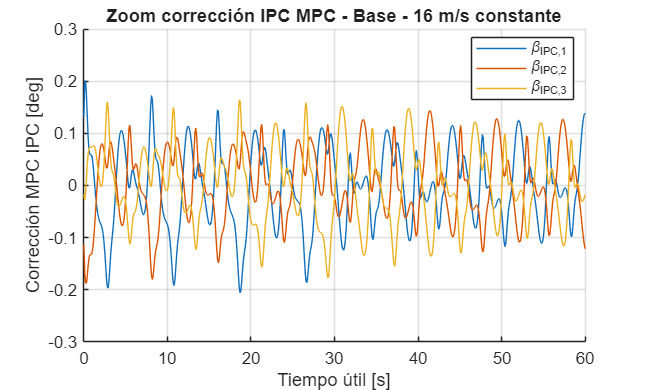

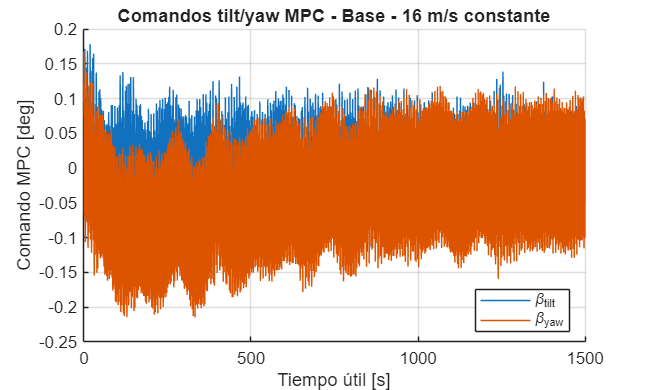


Leyendo caso para MPC offline: Base - 16 m/s turbulento


Reading from the file C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\CasoB_v16_turbulento\IEA-15-240-RWT-UMaineSemi.outb with heading: 
   "Predictions were generated on 11-Aug-2026 at 19:18:39 using OpenFAST, compiled on Aug 06 2025 at 19:22:48 as a 64-bit application using single precision at commit v4.1.2 linked with  NWTC Subroutine Library; ElastoDyn; InflowWind; AeroDyn; ServoDyn; SeaState; HydroDyn; MoorDyn (v2.3.8, 2025-02-27); Description from the FAST input file: IEA 15 MW offshore reference model on UMaine VolturnUS-S semi-submersible floating platform".


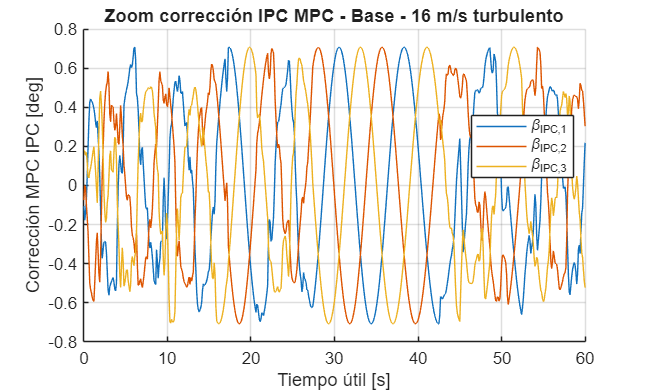

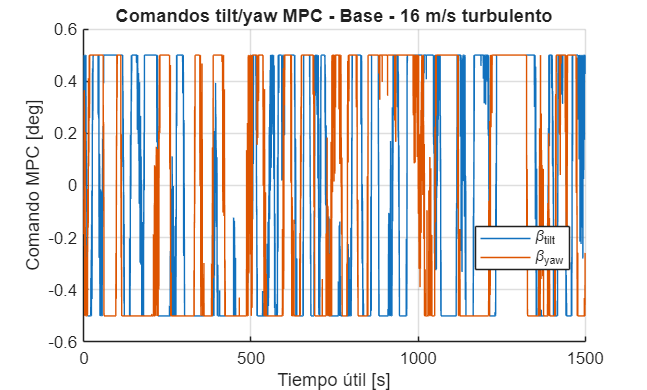

%% PRUEBA OFFLINE DEL MPC SOBRE CASOS BASE

rootDir = fullfile(getenv('USERPROFILE'), 'Desktop', 'TFM_OpenFast');
toolboxDir = fullfile(rootDir, 'Matlab', 'Matlab_Toolbox');
resRoot = fullfile(rootDir, 'Resultados');

addpath(genpath(toolboxDir));

outMPCDir = fullfile(resRoot, 'MPC_IPC', 'Offline');

if ~exist(outMPCDir, 'dir')
    mkdir(outMPCDir);
end

%% Casos base a probar

baseCases(1).name = "Base_constante";
baseCases(1).label = "Base - 16 m/s constante";
baseCases(1).dir = fullfile(resRoot, 'CasoA_v16_constante');

baseCases(2).name = "Base_turbulento";
baseCases(2).label = "Base - 16 m/s turbulento";
baseCases(2).dir = fullfile(resRoot, 'CasoB_v16_turbulento');

tTrans = 500;
betaRateMax_deg_s = 2;

mpcRows = {};

for k = 1:numel(baseCases)

    outbFile = fullfile(baseCases(k).dir, 'IEA-15-240-RWT-UMaineSemi.outb');

    fprintf("\nLeyendo caso para MPC offline: %s\n", baseCases(k).label);

    [X, ChanName, ChanUnit] = ReadFASTbinary(outbFile);

    C.X = X;
    C.names = cleanNames(ChanName);
    C.units = cleanNames(ChanUnit);
    C.t = getChan(C, "Time");
    C.idx = C.t >= tTrans;
    C.S = buildSignals(C);

    idx = C.idx;

    t = C.t(idx);
    tMPC = t - t(1);

    % Reducimos a Ts del MPC
    Ts = mpcobj.Ts;
    tGrid = (0:Ts:tMPC(end))';

    Mtilt = interp1(tMPC, C.S.Mtilt(idx), tGrid, 'linear', 'extrap') / 1000; % MNm
    Myaw  = interp1(tMPC, C.S.Myaw(idx),  tGrid, 'linear', 'extrap') / 1000; % MNm
    Azim  = interp1(tMPC, C.S.Azimuth(idx), tGrid, 'linear', 'extrap');

    % Quitar media para regular fluctuaciones alrededor del punto medio
    yMeas = [Mtilt - mean(Mtilt,'omitnan'), ...
             Myaw  - mean(Myaw,'omitnan')];

    r = [0 0];

    xmpc = mpcstate(mpcobj);

    betaTY = zeros(numel(tGrid),2);

    for i = 1:numel(tGrid)

        y = yMeas(i,:);

        % mpcmove calcula beta_tilt/beta_yaw en grados
        u = mpcmove(mpcobj, xmpc, y, r);

        betaTY(i,:) = u(:)';
    end

    beta_tilt = betaTY(:,1);
    beta_yaw  = betaTY(:,2);

    %% Transformación inversa MBC a pitch individual

    psi = deg2rad(Azim);

    beta1 = beta_tilt .* cos(psi) + beta_yaw .* sin(psi);
    beta2 = beta_tilt .* cos(psi + 2*pi/3) + beta_yaw .* sin(psi + 2*pi/3);
    beta3 = beta_tilt .* cos(psi + 4*pi/3) + beta_yaw .* sin(psi + 4*pi/3);

    betaIPC = [beta1 beta2 beta3];

    %% Métricas de esfuerzo

    betaRMS = sqrt(mean(betaIPC.^2, 1, 'omitnan'));
    betaMax = max(abs(betaIPC), [], 1);

    betaDot = zeros(size(betaIPC));

    for j = 1:3
        betaDot(2:end,j) = diff(betaIPC(:,j)) ./ diff(tGrid);
    end

    NAT_IPC_pct = 100 * mean(abs(betaDot), 1, 'omitnan') / betaRateMax_deg_s;

    mpcRows(end+1,:) = {
        char(baseCases(k).label), ...
        mean(betaRMS), ...
        max(betaMax), ...
        mean(NAT_IPC_pct), ...
        betaRMS(1), betaRMS(2), betaRMS(3), ...
        betaMax(1), betaMax(2), betaMax(3)
    };

    %% Guardar señales

    mpcTimeSeries = table( ...
        tGrid, ...
        beta_tilt, beta_yaw, ...
        betaIPC(:,1), betaIPC(:,2), betaIPC(:,3), ...
        yMeas(:,1), yMeas(:,2), ...
        'VariableNames', {'TimeUseful_s','BetaTilt_deg','BetaYaw_deg', ...
        'BetaIPC1_deg','BetaIPC2_deg','BetaIPC3_deg', ...
        'Mtilt_MNm_demean','Myaw_MNm_demean'} ...
    );

    writetable(mpcTimeSeries, fullfile(outMPCDir, sprintf('mpc_offline_%s.csv', baseCases(k).name)));

    %% Gráfica zoom IPC

    idxZoom = tGrid >= 0 & tGrid <= 60;

    figure;
    hold on; grid on;
    plot(tGrid(idxZoom), betaIPC(idxZoom,1), 'DisplayName','\beta_{IPC,1}');
    plot(tGrid(idxZoom), betaIPC(idxZoom,2), 'DisplayName','\beta_{IPC,2}');
    plot(tGrid(idxZoom), betaIPC(idxZoom,3), 'DisplayName','\beta_{IPC,3}');
    xlabel('Tiempo útil [s]');
    ylabel('Corrección MPC IPC [deg]');
    title("Zoom corrección IPC MPC - " + baseCases(k).label);
    legend('Location','best');

    saveas(gcf, fullfile(outMPCDir, sprintf('zoom_betaIPC_MPC_%s.png', baseCases(k).name)));

    %% Gráfica beta tilt/yaw

    figure;
    hold on; grid on;
    plot(tGrid, beta_tilt, 'DisplayName','\beta_{tilt}');
    plot(tGrid, beta_yaw, 'DisplayName','\beta_{yaw}');
    xlabel('Tiempo útil [s]');
    ylabel('Comando MPC [deg]');
    title("Comandos tilt/yaw MPC - " + baseCases(k).label);
    legend('Location','best');

    saveas(gcf, fullfile(outMPCDir, sprintf('betaTiltYaw_MPC_%s.png', baseCases(k).name)));
end


mpcOfflineSummary = cell2table(mpcRows, ...
    'VariableNames', {'Caso', ...
    'RMS_IPC_mean_deg','Max_IPC_deg','NAT_IPC_mean_pct', ...
    'RMS_beta1_deg','RMS_beta2_deg','RMS_beta3_deg', ...
    'Max_beta1_deg','Max_beta2_deg','Max_beta3_deg'});

disp("Resumen offline MPC:");

Resumen offline MPC:


disp(mpcOfflineSummary);

                Caso                RMS_IPC_mean_deg    Max_IPC_deg    NAT_IPC_mean_pct    RMS_beta1_deg    RMS_beta2_deg    RMS_beta3_deg    Max_beta1_deg    Max_beta2_deg    Max_beta3_deg
    ____________________________    ________________    ___________    ________________    _____________    _____________    _____________    _____________    _____________    _____________

    {'Base - 16 m/s constante' }        0.070632          0.21428           6.3386           0.070947         0.068865         0.072085          0.20817          0.21428          0.21274   
    {'Base - 16 m/s turbulento'}         0.46961          0.70711           20.881       


writetable(mpcOfflineSummary, fullfile(outMPCDir, 'resumen_offline_MPC.csv'));

save(fullfile(outMPCDir, 'mpc_offline_resultados.mat'), ...
    'mpcOfflineSummary', 'mpcobj');

disp("Prueba offline MPC terminada.");

Prueba offline MPC terminada.


disp(outMPCDir);

C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\MPC_IPC\Offline


Funciones

function names = cleanNames(raw)

    if ischar(raw)
        names = string(cellstr(raw));
    elseif isstring(raw)
        names = raw(:);
    elseif iscell(raw)
        names = strings(numel(raw),1);

        for i = 1:numel(raw)
            item = raw{i};

            if iscell(item)
                item = item{1};
            end

            names(i) = string(item);
        end
    else
        error("Formato de nombres no reconocido.");
    end

    names = strtrim(names(:));
end

function y = getChan(C, name)

    idx = find(strcmpi(C.names, name), 1);

    if isempty(idx)
        warning("Canal no encontrado: %s", name);
        y = nan(size(C.X,1),1);
    else
        y = C.X(:,idx);
    end
end

function S = buildSignals(C)

    S.GenPwr_MW = getChan(C, "GenPwr") / 1000;
    S.RotSpeed  = getChan(C, "RotSpeed");
    S.Azimuth   = getChan(C, "Azimuth");

    S.BldPitch1 = getChan(C, "BldPitch1");
    S.BldPitch2 = getChan(C, "BldPitch2");
    S.BldPitch3 = getChan(C, "BldPitch3");

    S.PtfmSurge = getChan(C, "PtfmSurge");
    S.PtfmPitch = getChan(C, "PtfmPitch");

    S.RootMyb1 = getChan(C, "RootMyb1");
    S.RootMyb2 = getChan(C, "RootMyb2");
    S.RootMyb3 = getChan(C, "RootMyb3");

    psi = deg2rad(S.Azimuth);

    S.Mtilt = (2/3) .* ( ...
        S.RootMyb1 .* cos(psi) + ...
        S.RootMyb2 .* cos(psi + 2*pi/3) + ...
        S.RootMyb3 .* cos(psi + 4*pi/3));

    S.Myaw = (2/3) .* ( ...
        S.RootMyb1 .* sin(psi) + ...
        S.RootMyb2 .* sin(psi + 2*pi/3) + ...
        S.RootMyb3 .* sin(psi + 4*pi/3));
end


El MPC consigue generar señales IPC acotadas y coherentes, con una amplitud máxima próxima a 0.7∘, comparable a las estrategias IPC implementadas en OpenFAST. En el caso turbulento, la actividad del actuador estimada mediante NAT es menor que en los controladores IPC integral y PI, lo que muestra el potencial del MPC para incorporar restricciones de pitch y suavizar la actuación.